# Process the intensity data from Idler

Theta = (0,2) degrees.

kerker_slab_silicon_1


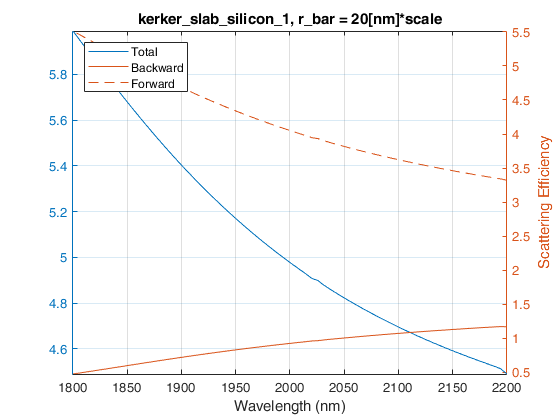

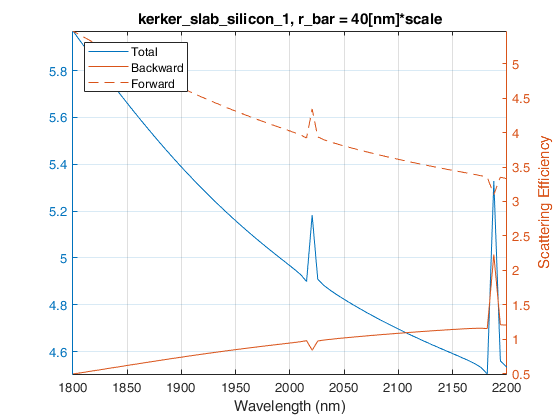

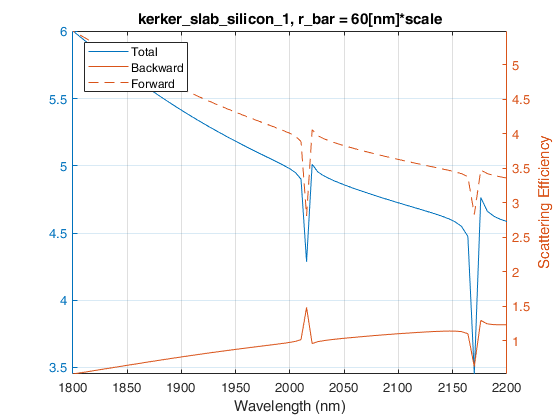

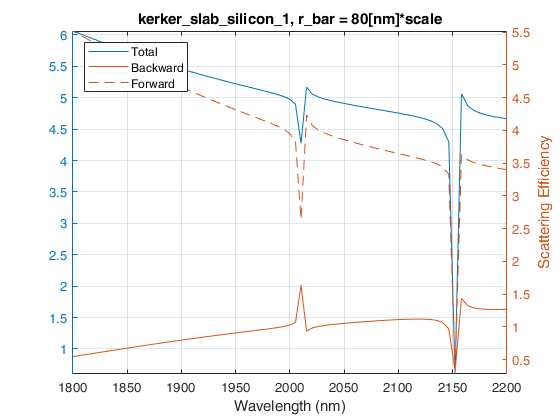

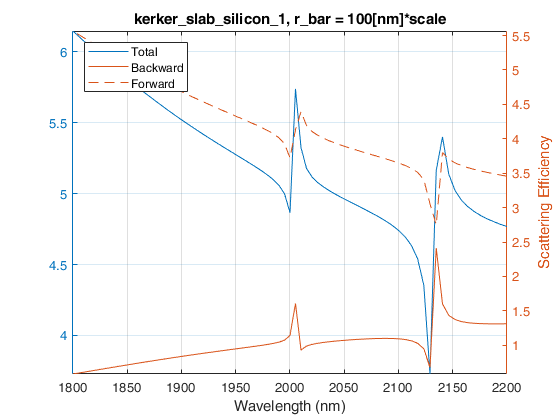

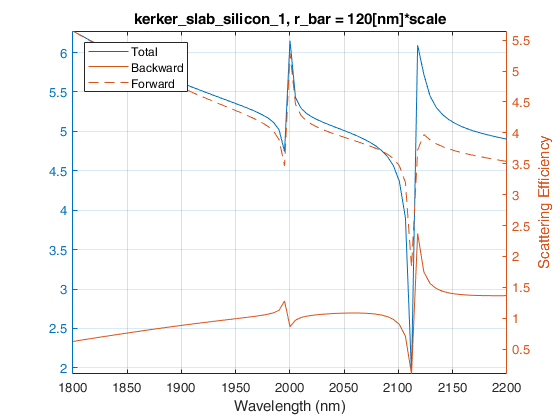

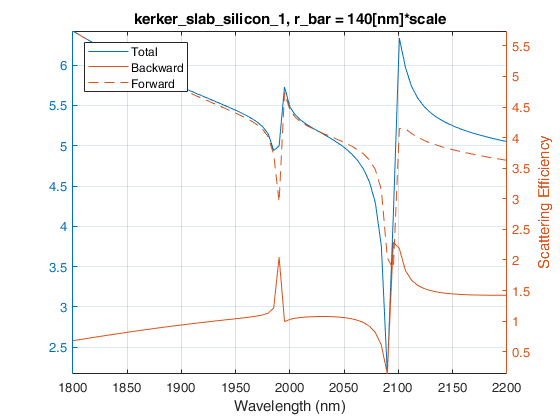

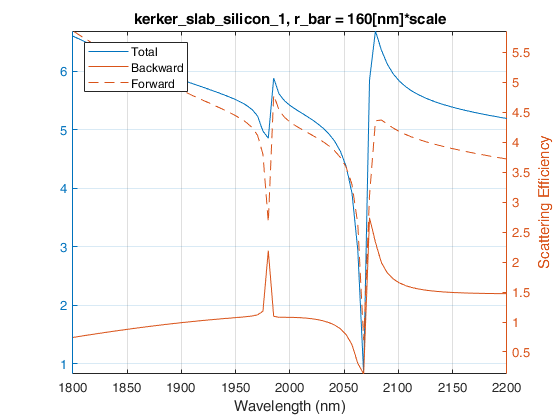

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed');

cylinder_dimer_no_substrate_110_13 = ["cylinder_dimer_no_substrate_110_13_1",...
    "cylinder_dimer_no_substrate_110_13_2","cylinder_dimer_no_substrate_110_13_3",...
    "cylinder_dimer_no_substrate_110_13_4","cylinder_dimer_no_substrate_110_13_5",...
    "cylinder_dimer_no_substrate_110_13_6","cylinder_dimer_no_substrate_110_13_7",...
    "cylinder_dimer_no_substrate_110_13_8","cylinder_dimer_no_substrate_110_13_9",...
    "cylinder_dimer_no_substrate_110_13_11","cylinder_dimer_no_substrate_110_13_12"];
cylinder_dimer_no_substrate_110 = ["cylinder_dimer_no_substrate_110_2",...
    "cylinder_dimer_no_substrate_110_3","cylinder_dimer_no_substrate_110_4",...
    "cylinder_dimer_no_substrate_110_5","cylinder_dimer_no_substrate_110_6",...
    "cylinder_dimer_no_substrate_110_7","cylinder_dimer_no_substrate_110_8",...
    "cylinder_dimer_no_substrate_110_9","cylinder_dimer_no_substrate_110_10"];

sfg_enhancement = [];
intensity_enhancement = [];
idler_enhancement = [];

for job = "kerker_slab_silicon_1"
%for job = "paris_2"
    eval(job);
    load([options.output_dir_final 'sweep_data.mat']);
    extra_options = matthew_extra_options(options);
    disp(job);
    
    for study_num = 1:height(sweep_data)
        derived_values = sweep_data(study_num,:).DerivedValues{1};
        
        wlengths = 299792458./derived_values.signal.freq;
        surface_area = derived_values.signal.surface_area(1);
        
        intensity_enhancement = [intensity_enhancement,...
                max(derived_values.signal.max_Is)/min(derived_values.signal.max_Is)]; 
%        idler_enhancement = [idler_enhancement,...
%                max(derived_values.idler.max_Is)/min(derived_values.idler.max_Is)];
        %sfg_enhancement = [sfg_enhancement max(derived_values.sfg.scat3_eff)/derived_values.sfg.scat3_eff(1)];
        
        figure;
        yyaxis left;
        plot(wlengths,derived_values.signal.scat_eff);
        %plot((1:length(derived_values.sfg(theta_ind).ind_frq)),derived_values.signal(theta_ind).scat_eff); % scat3_eff
        hold on
        %plot(wlengths,derived_values.idler(theta_ind).scat2_eff);
        %plot((1:length(derived_values.sfg(theta_ind).ind_frq)),derived_values.idler(theta_ind).scat2_eff); % max_Isfg
        %ylabel('Linear Scattering Efficiency');
        yyaxis right;
        plot(wlengths,(derived_values.signal.sigma_scup/surface_area)); 
        plot(wlengths,(derived_values.signal.sigma_scdn/surface_area)); 
        %plot(wlengths,log10(derived_values.sfg.scat3_eff)); % int_Isfg
        %plot(wlengths,log10(derived_values.signal.max_Is)); % int_Isfg
        leg_scat3 = legend({'Total','Backward','Forward'});
        leg_scat3.Location = 'northwest';
        xlabel('Wavelength (nm)');
        ylabel('Scattering Efficiency');
        axis tight;
        grid on;
        %title(strcat('\Theta = ', num2str((theta_ind-1)*0.1), ' deg.'));
        title(strcat(job, ", ", sweep_data(study_num,1).Properties.VariableNames{1},...
            " = ", sweep_data{study_num,1}), 'Interpreter', 'none');
    end
end